% Microwave Project
% Create data structure
%ZO = 50 Ω, TA = 25°C, VCE = 8 V, IC = 10 mA
data10 = [
0.1 .74 -38 28.1 25.46 157 -39.6 .011 68 .94 -12 10;
0.5 .59 -127 22.0 12.63 107 -30.2 .031 47 .60 -29 10;
1.0 .56 -168 16.8 6.92 84 -27.7 .041 46 .49 -29 10;
1.5 .57 169 13.5 4.72 69 -26.2 .049 49 .45 -32 10;
2.0 .62 152 11.1 3.61 56 -24.8 .058 43 .42 -39 10;
2.5 .63 142 9.3 2.91 47 -23.4 .068 52 .40 -42 10;
3.0 .64 130 7.6 2.41 37 -22.2 .078 52 .39 -50 10;
3.5 .68 122 6.3 2.06 26 -20.6 .093 51 .37 -60 10;
4.0 .71 113 5.1 1.80 16 -19.5 .106 48 .35 -70 10;
4.5 .74 105 4.0 1.59 7 -18.0 .125 48 .35 -84 10;
5.0 .77 99 3.1 1.42 -4 -17.2 .139 43 .35 -98 10;
5.5 .79 93 2.0 1.27 -13 -16.3 .153 38 .35 -114 10;
6.0 .81 87 1.1 1.13 -22 -15.4 .170 34 .35 -131 10;
];
%ZO = 50 Ω, TA = 25°C, VCE = 8 V, IC = 25 mA
data25 = [
    0.1 .50 -75 32.0 40.01 142 -41.3 .009 54 .85 -17 25;
    0.5 .55 -158 23.2 14.38 97 -34.1 .020 48 .51 -24 25;
    1.0 .57 177 17.5 7.50 78 -29.9 .032 61 .46 -24 25;
    1.5 .57 161 14.1 5.07 65 -27.3 .043 62 .44 -28 25;
    2.0 .59 148 11.5 3.75 53 -24.8 .058 59 .43 -35 25;
    2.5 .61 139 9.6 3.02 45 -22.9 .072 58 .40 -41 25;
    3.0 .65 128 8.0 2.52 34 -21.6 .083 57 .38 -49 25;
    3.5 .70 121 6.7 2.17 24 -20.1 .099 56 .36 -59 25;
    4.0 .74 113 5.7 1.92 14 -18.8 .115 52 .34 -72 25;
    4.5 .78 107 4.7 1.72 3 -17.6 .132 47 .32 -87 25;
    5.0 .78 102 3.7 1.53 -8 -16.6 .149 42 .31 -106 25;
    5.5 .78 96 2.7 1.36 -19 -15.4 .169 36 .31 -125 25;
    6.0 .76 91 1.6 1.21 -29 -14.5 .188 31 .33 -144 25;    
];


Data = {data10, data25};

[S, f] = extractSparams(Data);


% on ustrip line, width used to change Z0, length used to change f0



% Interpolate S Params

% Center frequency of amplifier
f0 = 3.3e9;

% Only care about 25 mA values for now
idx = 2;

S11 = [];
S12 = [];
S21 = [];
S22 = [];

for k = 1:length(S)
    S11(k) = S{idx,k}(1,1);
    S12(k) = S{idx,k}(1,2);
    S21(k) = S{idx,k}(2,1);
    S22(k) = S{idx,k}(2,2);
end

% Split into mag/ phase for fitting
S11mag = abs(S11);
S11arg = angle(S11);
S12mag = abs(S12);
S12arg = angle(S12);
S21mag = abs(S21);
S21arg = angle(S21);
S22mag = abs(S22);
S22arg = angle(S22);

% Interpolate the data
S11magInterp = interpFit(f, S11mag);
S11argInterp = interpFit(f, S11arg);

S12magInterp = interpFit(f, S12mag);
S12argInterp = interpFit(f, S12arg);

S21magInterp = interpFit(f, S21mag);
S21argInterp = interpFit(f, S21arg);

S22magInterp = interpFit(f, S22mag);
S22argInterp = interpFit(f, S22arg);


% Generate interpolated data
fInterp = linspace(1,6,1000)*1e9;
S11Interp = S11magInterp(fInterp).*exp(j*S11argInterp(fInterp));
S12Interp = S12magInterp(fInterp).*exp(j*S12argInterp(fInterp));
S21Interp = S21magInterp(fInterp).*exp(j*S21argInterp(fInterp));
S22Interp = S22magInterp(fInterp).*exp(j*S22argInterp(fInterp));

deltaInterp = S11Interp.*S22Interp - S12Interp.*S21Interp;
tol = 1.1*mean(diff(fInterp));
f0Idx = find(fInterp <= f0 + tol & fInterp >= f0 - tol);
f0Idx = f0Idx(1);

% Get S params for center frequency
S = [S11magInterp(f0).*exp(j*S11argInterp(f0)),...
    S12magInterp(f0).*exp(j*S12argInterp(f0));...
    S21magInterp(f0).*exp(j*S21argInterp(f0)),...
    S22magInterp(f0).*exp(j*S22argInterp(f0))];

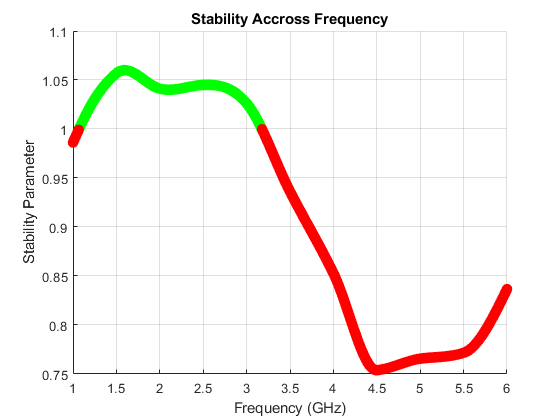

% Check Stability -> TLDR: Potentially Unstable 
K = (1-abs(S(1,1))^2-abs(S(2,2))^2+abs(det(S))^2);
K = K/(2*abs(S(1,2)*S(2,1)));

% Stability param accross frequency
mu = 1 - abs(S11Interp).^2;
mu = mu./(abs(S22Interp-deltaInterp.*conj(S11Interp)) + abs(S12Interp.*S21Interp));

% Plot Stability Param
theValue = 1;
aboveLine = mu > theValue; % or whatever.
hold off
hold on;
% Plot above line in green.
scatter(fInterp(aboveLine)/1e9, mu(aboveLine), 'g',  'LineWidth', 2);
% Plot below line in red.
scatter(fInterp(~aboveLine)/1e9, mu(~aboveLine), 'r', 'LineWidth', 2);
xlabel('Frequency (GHz)')
ylabel('Stability Parameter')
title('Stability Accross Frequency')
grid on

% Find the Stability Circles
% Output for Gamma L
centerOutput = conj(S22Interp - abs(deltaInterp).*conj(S11Interp));
centerOutput = centerOutput./(abs(S22Interp).^2 - abs(deltaInterp).^2);

radiusOutput = S12Interp.*S21Interp;
radiusOutput = radiusOutput./(abs(S22Interp).^2 - abs(deltaInterp).^2);
radiusOutput = abs(radiusOutput);

% Input for Gamma S
centerInput = conj(S11Interp - abs(deltaInterp).*conj(S22Interp));
centerInput = centerInput./(abs(S11Interp).^2 - abs(deltaInterp).^2);

radiusInput = S12Interp.*S21Interp;
radiusInput = radiusInput./(abs(S11Interp).^2 - abs(deltaInterp).^2);

% Plot The Stability Circles
skipFactor = 50;
legendText = {};
for k = 1:round(length(fInterp)/skipFactor)
    subplot(1,2,1)
    xS = real(centerInput(k*skipFactor));
    yS = imag(centerInput(k*skipFactor));
    rS = radiusInput(k*skipFactor)
    inputStabilityCircle = smithCircle(xS,yS,rS);
    
    subplot(1,2,2)
    xL = real(centerOutput(k*skipFactor));
    yL = imag(centerOutput(k*skipFactor));
    rL = radiusOutput(k*skipFactor)
    outputStabilityCircle = smithCircle(xL,yL,rL);
    legendText{k} = strcat('f = ', num2str(fInterp(k*skipFactor)/1e9), 'GHz');
    pause(1)
end
subplot(1,2,1)
title('Gamma S')
legend(legendText)
subplot(1,2,2)
title('Gamma L')
legend(legendText)



% Finding the Gammas

% Unilateral Approach -> this assumption makes the amp unconditionally
% stable when it actually isn't
GammaIn = S(1,1);
GammaOut = S(2,2);

GammaS = conj(GammaIn);
GammaL = conj(GammaOut);

% Check for stability
% Output
centerL = centerOutput(f0Idx);
radiusL = radiusOutput(f0Idx);
assert(abs(GammaL) < abs(centerL) - abs(radiusL))
xL = real(centerL);
yL = imag(centerL);
rL = radiusL;
subplot(1,2,2)
circle(xL,yL,rL)
hold on
plot(real(GammaL), imag(GammaL), 'x')
axis square
xlim([-1 1])
ylim([-1 1])
circle(0,0,1)
grid on
title('Gamma L Plane')

% Input
centerS = centerInput(f0Idx);
radiusS = radiusInput(f0Idx);
assert(abs(GammaS) < abs(centerS) - abs(radiusS))
xS = real(centerS);
yS = imag(centerS);
rS = radiusS
subplot(1,2,1)
circle(xS,yS,rS)
hold on
plot(real(GammaS), imag(GammaS), 'x')
axis square
xlim([-1 1])
ylim([-1 1])
circle(0,0,1)
grid on
title('Gamma S Plane')


% Getting Gammas -> unilateral assumption
% Gammas are still rather large though :/
B1 = 1 + abs(S(1,1))^2 - abs(S(2,2))^2 - abs(S(1,1)*S(2,2))^2;
B2 = 1 - abs(S(1,1))^2 + abs(S(2,2))^2 - abs(S(1,1)*S(2,2))^2;
C1 = S(1,1) - abs(S(1,1)*S(2,2))*conj(S(2,2));
C2 = S(2,2) - abs(S(1,1)*S(2,2))*conj(S(1,1));

gammaMS = B1^2 - 4*abs(C1)^2;
gammaMS = B1 - sqrt(gammaMS);
gammaMS = gammaMS/(2*C1)

gammaML = B2^2 - 4*abs(C2)^2;
gammaML = B2 - sqrt(gammaML);
gammaML = gammaML/(2*C2)

% Finding the required matching network input impedances 
Z0 = 50;
Zinput = (1+GammaS)/(1-GammaS)*Z0 
Zoutput = (1+GammaL)/(1-GammaL)*Z0


% Finding the expected unilateral gain
G0 = abs(S(2,1))^2;

Gs = 1 - abs(GammaS)^2;
Gs = Gs/abs(1 - S(1,1)*GammaS)^2;

Gl = 1 - abs(GammaL)^2;
Gl = Gl/abs(1 - S(2,2)*GammaL)^2;

Gain = Gs*G0*Gl
GaindB = 10*log10(Gain)

% Find Error Bounds
unilateralFigureOfMerit = abs(S(1,1)*S(1,2)*S(2,1)*S(2,2));
unilateralFigureOfMerit = unilateralFigureOfMerit/(1-abs(S(1,1))^2)/(1-abs(S(2,2))^2);

lowerGainErrorBound = 1/(1+unilateralFigureOfMerit)^2;
lowerGainErrorBounddB = 10*log10(lowerGainErrorBound)

upperGainErrorBound = 1/(1-unilateralFigureOfMerit)^2;
upperGainErrorBound = 10*log10(upperGainErrorBound)

% Printing out the Results
disp(strcat('System Impedance: ', num2str(Z0), 'Ω'))

disp('For the input matching network: ')
disp(strcat('Gamma looking towards gen from transistor: ', num2str(abs(GammaS)), '∠', num2str(angle(GammaS)*180/pi), '°'))
disp(strcat('Corrissponding Z: ', num2str(Zinput), 'Ω'))

disp('For the output matching network:')
disp(strcat('Gamma looking towards load from transistor: ', num2str(abs(GammaL)), '∠', num2str(angle(GammaL)*180/pi), '°'))
disp(strcat('Corrissponding Z: ', num2str(Zoutput), 'Ω'))

disp('Gain Info')
disp(strcat('Expected gain @  ', num2str(f0/1e9), 'GHz: ', num2str(GaindB), 'dB'))
disp(strcat('Gain error bounds [', num2str(lowerGainErrorBound), ', ', num2str(upperGainErrorBound), '] dB'))


% Not using this anymore
% gammaS = conj(S33(1,1));

% Getting Gammas

% B1 = 1 + abs(S(1,1))^2 - abs(S(2,2))^2 - abs(det(S))^2;
% B2 = 1 - abs(S(1,1))^2 + abs(S(2,2))^2 - abs(det(S))^2;
% C1 = S(1,1) - abs(det(S))*conj(S(2,2));
% C2 = S(2,2) - abs(det(S))*conj(S(1,1));
% 
% gammaMS = B1^2 - 4*abs(C1)^2;
% gammaMS = B1 - sqrt(gammaMS);
% gammaMS = gammaMS/(2*C1)
% 
% gammaML = B2^2 - 4*abs(C2)^2;
% gammaML = B2 - sqrt(gammaML);
% gammaML = gammaML/(2*C2)
% 
% gaMax = K - sqrt(K^2 - 1);
% gaMax = gaMax/abs(S33(1,2)*S33(2,1));
% GAMax = abs(S33(2,1))*(K - sqrt(K^2 - 1));
% GAMax = GAMax/abs(S33(1,2));



